% NaN data processing
A = [1 2 3; NaN NaN NaN; 4 5 6];
disp(A);

     1     2     3
   NaN   NaN   NaN
     4     5     6



isnan(A)

ans = 3×3 logical 数组
   0   0   0
   1   1   1
   0   0   0


any(isnan(A))

ans = 1×3 logical 数组
   1   1   1


% remove all row with NaN
A(any(isnan(A')), :) = [];
disp(A);

     1     2     3
     4     5     6



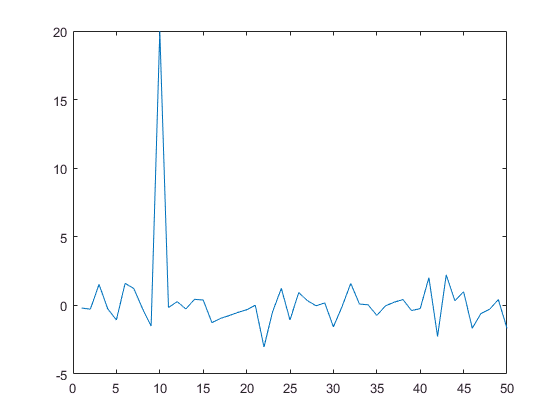

% Abnormal data processing
a = normrnd(0, 1, 1, 50);
a(10) = 20; % create a abnormal data
plot(a);

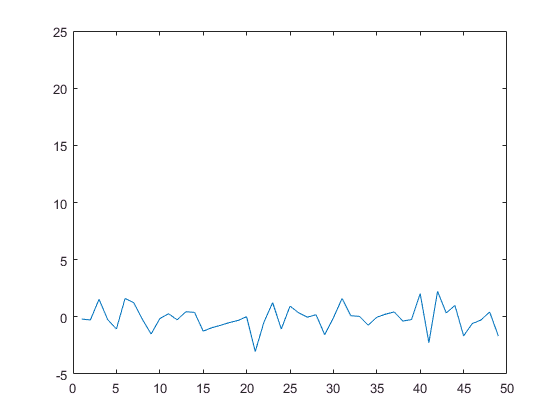

figure;
b = a(abs(a-mean(a)) <= 3*std(a));
plot(b);
ylim([-5 25]);

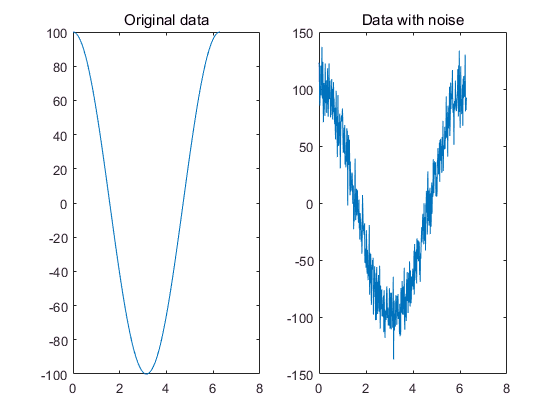

% Smooth
x = linspace(0, 2*pi, 500);
y = 100 * cos(x);
subplot(1, 2, 1);
plot(x, y);
title('Original data');
noise = normrnd(0, 15, 1, 500);
yn = y + noise;
subplot(1, 2, 2);
plot(x, yn);
title('Data with noise');

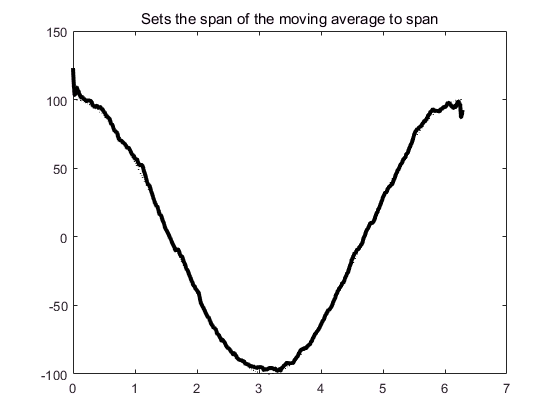


% Smooth processing
y1 = smooth(yn, 30);
figure;
plot(x, y, 'k:');
hold on;
plot(x, y1, 'k', 'linewidth', 3);
title('Sets the span of the moving average to span');

% Data standarlize
A = magic(6);
[Z, mu, sigma] = zscore(A);
disp(Z); disp(mu); disp(sigma);

    1.1017   -1.1502   -0.8346    1.3716    0.0821    1.0058
   -1.0349    0.8873   -0.7679    0.4572    0.7388    1.1887
    0.8346   -0.6244   -1.1017    0.6401    1.3955    0.2743
   -0.7011    0.6244    0.9682   -0.2743   -1.3955   -0.6401
    0.7679   -0.8873    1.0349   -1.1887   -0.7388   -0.4572
   -0.9682    1.1502    0.7011   -1.0058   -0.0821   -1.3716

   18.5000   18.5000   18.5000   18.5000   18.5000   18.5000

   14.9766   15.2151   14.9766    5.4681    6.0910    5.4681



% mapminmax(X, min, max)
Y = mapminmax(A, -2, 2);
disp(Y);

    2.0000   -2.0000   -1.4118    0.9412    0.1176    0.7059
   -2.0000    2.0000   -1.4483    0.4828    0.7586    1.0345
    2.0000   -1.0345   -2.0000    0.7586    1.4483    0.4828
   -2.0000    1.2000    2.0000   -0.5600   -1.6800   -0.8800
    1.4483   -2.0000    2.0000   -1.0345   -0.7586   -0.4828
   -2.0000    2.0000    1.1250   -0.8750   -0.2500   -1.1250

